rng(0);

A = Problem.A;
size(A)

ans =        49152       49152


r = rand(size(A,1),1);

mmax = 50;

d = eigs(A);

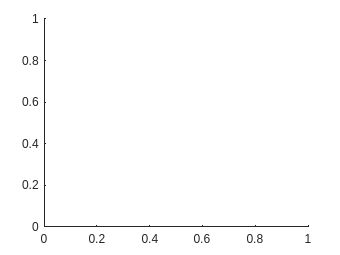

scatter(real(d), imag(d), 'r*');
hold on;

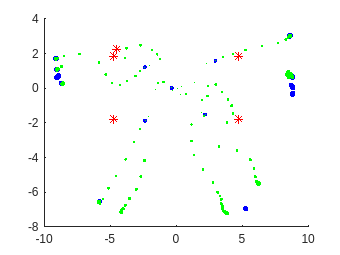

for m = 1:50
    [V, H] = arnoldi(A, r, m);
    dh = eigs(H(1:m,1:m));
    scatter(real(dh), imag(dh), m, 'g.');
end


hold off;

[Ve, De] = eigs(A);

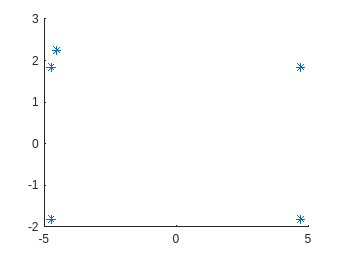

scatter(real(diag(De)), imag(diag(De)), '*');
hold on;

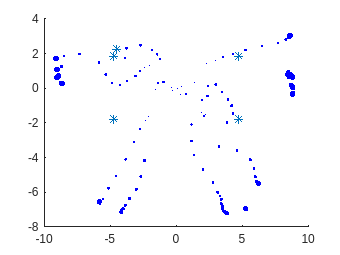

for m = 1:mmax
    [~, Ha] = arnoldi(A, r, m);
    [Va, Ea] = eigs(Ha(1:m,:));
    scatter(real(diag(Ea)), imag(diag(Ea)),100* m/mmax ,'b.');
end
hold off;